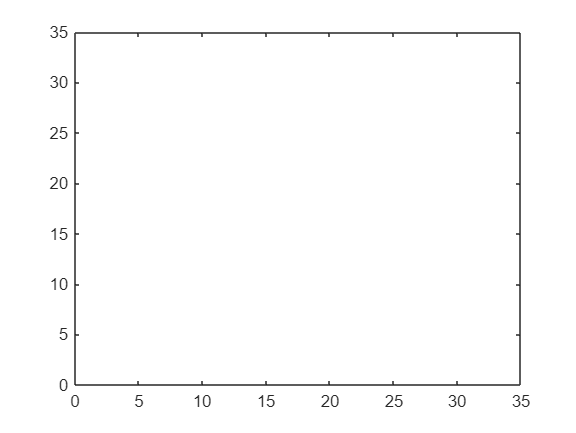

% a computational tool to calculate the capacitance of a rectangular prisim
% (3D!) composed of two plates parallel to x-y plane
% currently does not work :D

clear all;
clc;
%Grid dimensions
xdim=30;
ydim=30;
zdim=30;
dx = 0.00001;             % grid spacing (1 mm, arbitrary scaling)
dy = 0.00001;
dz = 0.00001;
%Initialize voltage matricies
V_now=zeros(xdim+1, ydim+1, zdim+1);
V_prev=zeros(xdim+1, ydim+1, zdim+1);
%Initializing boundary conditions (capacitor plates)
V_now(:, :, 1) = 0;          % bottom plate 0V (bottom plate is z = 0)
V_now(:, :, zdim+1) = 10;    % top plate 10V
%Iteration counter
iter=0;
%Calculation of maximum error between V_now and V_prev at all points
%By setting the applied voltage for only V_now, we have made V_no and
%V_prev different, hence error will be greater than zero and the program
%will enter the while loop following this command.
error=max(max(abs(V_now-V_prev)));
%Iteration loop
while(error>0.01)%Run this until convergence
    
    iter=iter+1; % Iteration counter increment
    
    % Updating present iteration using 6? point Central diffrence form
    % of Laplace equation obtained using Finite Difference method
    for i = 2:xdim
        for j = 2:ydim
            for k = 2:zdim
                V_now(i, j, k) = (V_now(i-1, j, k)+V_now(i+1, j, k)+V_now(i, j-1, k)+V_now(i, j+1, k)+V_now(i, j, k-1)+V_now(i, j, k+1))/4;
            end
        end
    end
    error=max(max(abs(V_now-V_prev))); % Calculate the maximum error between previous and current iteration at all points
    V_prev=V_now; % Updating previous iteration matrix to the last iteration performed
    
    %Movie type colour scaled image plot to see how solution progresses
    imagesc(V_now);colorbar;
    title(['Voltage distribution on a ',int2str(xdim),' x ',int2str(ydim),' grid at iteration no ',int2str(iter)],'Color','k'); 
    getframe;
end
%Plot the electric field distribution
figure;
[ex, ey, ez]=gradient(V_now, dx, dy, dz);
ex = -ex;
ey = -ey;
ez = -ez;
quiver(ex, ey); %Quiver command creates a plot, E=-grad(V), hence the negative sign

                % currently quiver is making a 2d plot of just the x and y
                % components?
%Calculate capacitance
epsilon0 = 1; % Vacuum permittivity -- set to 1 for testing purposes
Ex_top = -ex(:, end-1);          % field just below the top plate
rho_s_top = epsilon0 * Ex_top; % negative because normal points downward
Q_top = sum(rho_s_top) * dx; % dx * dy * ydim; Maybe edit????
C = Q_top / 10; %C = total charge / applied voltage
C_total = C;
